# **Unsupervised Learning - Motion**

clc; clear; close all;

#### Load Data

load posdata.mat
load video4.mat

#### **Data Information**

- The movement data of cuttle fish's body parts from 5 videos. 

- Each video consists of 20 frames

- Tracked (x, y) position of 5 body parts (dorsal mantle end,  left eye, right eye, left tentacle club tips, right tentacle club tips)

disp(posdata)

    {20×1 struct}    {20×1 struct}    {20×1 struct}    {20×1 struct}    {20×1 struct}



disp(posdata{1}) % x and y position of 5 body parts

  다음 필드를 포함한 20×1 struct 배열:

    x1
    y1
    x2
    y2
    x3
    y3
    x4
    y4
    x5
    y5



% Convert cell structure into usable numberic matrices
datatmp     = cellfun(@struct2cell, posdata,'UniformOutput',false);
datatmp     = cellfun(@cell2mat,datatmp','UniformOutput',false);
data_pos    = cellfun(@transpose,datatmp,'UniformOutput',false);

% Processed position data (video 1)
disp(data_pos{1})

  1 ~ 9번 열

  443.6025  231.9903  327.7598  332.4595  382.7580  362.5570  307.6227  405.4296  311.9532
  406.1234  215.2277  315.4177  331.5934  373.4473  355.1950  316.2838  406.7288  319.5317
  400.7848  207.2198  330.1416  333.1091  387.7382  354.3289  330.3582  389.1900  333.3896
  410.9282  211.4907  336.8540  336.5736  394.4506  357.5768  337.2871  390.7057  341.4011
  441.8922  225.1041  358.5068  344.3686  414.1547  368.6198  361.3217  395.2528  364.5697
  509.9596  268.8808  390.9861  356.7107  443.1695  390.9222  382.1084  406.0792  384.7068
       NaN       NaN  405.0605  387.6743  452.9132  426.8659  407.2257  435.0940  411.1233
  470.9877  273.9525  405.2770  385.2925  468.0702  409.7602  420.6505  489.4426  425.1976
  425.3425  243.7893  376.0456  382.4776  440.1381  385.9420  376.0456  442.4560  412.6390
  381.8327  237.1160  356.3416  377.7140  420.0009  377.9305  382.9746  432.2791  394.0175
  373.6638  235.6713  333.1730  372.3008  397.6985  377.9305  337.5036  432.71

% Define Variables
n_frames = 20;
n_videos = 5;
n_joint  = 5;

% Define body part names
jointname = {'dorsal mantle end'; 'left eyes'; 'right eyes'; ...
    'left tentacle club tips'; 'Right tentacle club tips'};

#### Draw Trajectory (Data Visualization)

colors = [1.0000 0.3000 0.3000;
        0.9000 0.8000 0.3000;
        0.4660 0.6740 0.1880;
        0.3000 0.7450 0.9330;
        0.6000 0.2500 0.6500];
i_video = 4;

xidx    = [1 3 5 7 9];  % columns containing the x positions
yidx    = [2 4 6 8 10]; % columns containing the y positions

Xpos = data_pos{i_video}(:,xidx);
Ypos = data_pos{i_video}(:,yidx);

[nanidx,~]     = find(isnan(Xpos));
Xpos(nanidx,:) = [];
Ypos(nanidx,:) = [];

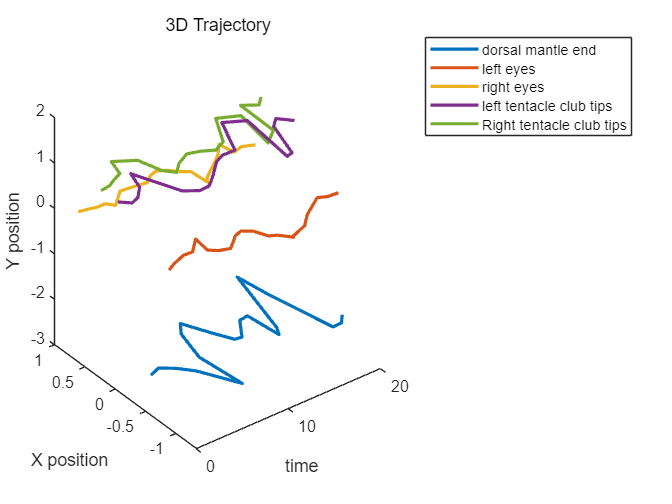

% Normalization
Xpos = (Xpos-mean(Xpos,2))./std(Xpos);
Ypos = (Ypos-mean(Ypos,2))./std(Ypos);

t = 1:length(Xpos);

% Draw 3d trajectories (time,x,y)
figure;
plot3(t,Xpos,Ypos,'LineWidth',2)
xlabel('time')
ylabel('X position')
zlabel('Y position')
title('3D Trajectory')
legend(jointname)

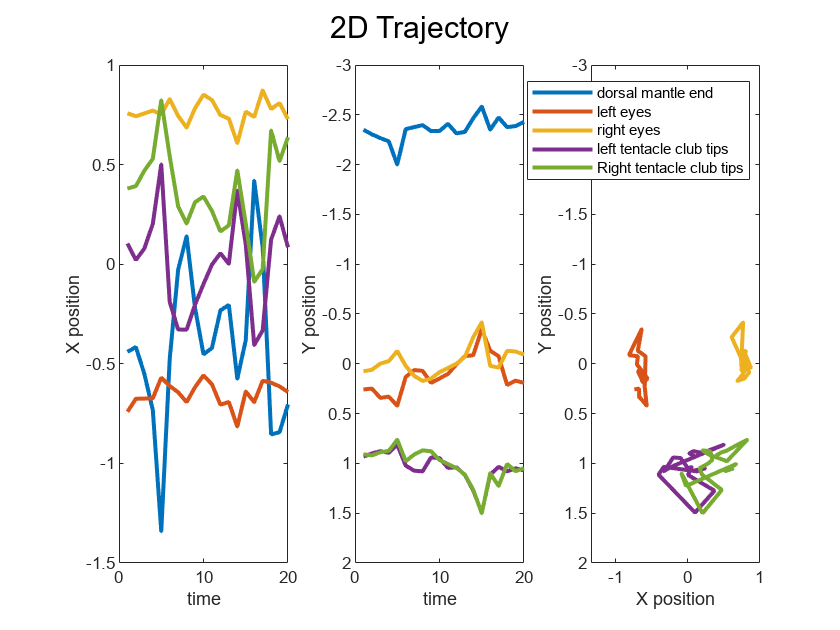

% Draw 2d trajectories
figure;
subplot(1,3,1)
plot(t,Xpos,'LineWidth',2);
xlabel('time'); ylabel('X position');
subplot(1,3,2)
plot(t,Ypos,'LineWidth',2);
axis ij % transpose y direction
xlabel('time'); ylabel('Y position');
subplot(1,3,3)
plot(Xpos,Ypos,'LineWidth',2);
xlabel('X position'); ylabel('Y position');
axis ij
legend(jointname)
sgtitle('2D Trajectory')

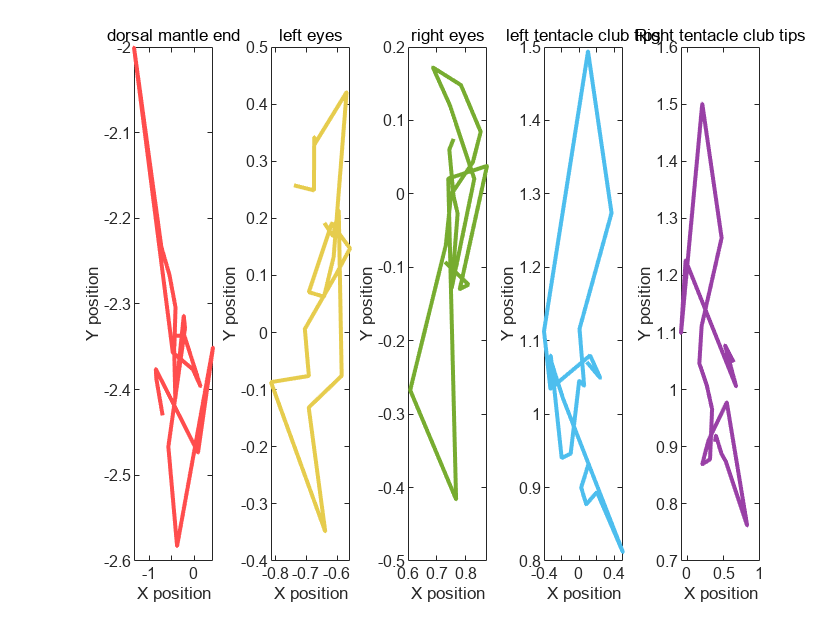

% Draw individual trajectories for each body parts
figure;
for i_joint = 1:n_joint
    subplot(1,5,i_joint)
    plot(Xpos(:,i_joint),Ypos(:,i_joint),'LineWidth',2,'Color',colors(i_joint,:));
    xlabel('X position')
    ylabel('Y position')
    title(jointname(i_joint))
end

% index club tips strike-timing
for i_joint = 4:5
    [~,t_strike] = max(Ypos(:,i_joint));
    disp(t_strike)
end

    15

    15



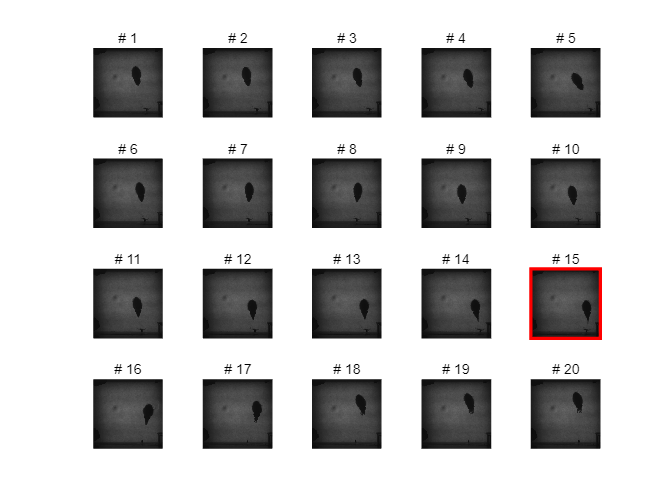

figure
for i_frame = 1:n_frames
    subplot(4,5,i_frame)
    imshow(frame{i_frame});
    title(['# ',num2str(i_frame)])
    hold on;

    % highlight frame of t_strike
    if i_frame == t_strike
        rectangle('Position', [1, 1, size(frame{i_frame}, 2)-1, size(frame{i_frame}, 1)-1], 'EdgeColor', 'r', 'LineWidth', 2);
    end

    hold off;
end

#### PCA (Principal Component Analysis)

XY_pos = [Xpos Ypos];

#### `!!!Fill the blank!!!`

% Perform PCA
[pc, score, latent, ~, explained] = pca(XY_pos);

% Check the explained variance for each PC
disp([explained cumsum(explained)])

   69.7196   69.7196
   22.5485   92.2681
    3.6146   95.8827
    2.3398   98.2226
    1.0928   99.3153
    0.4292   99.7445
    0.1858   99.9304
    0.0696  100.0000
    0.0000  100.0000
    0.0000  100.0000



% Reconstruct
% Multiply inverse of coefficient to projection
n_pc = 3;

#### `!!!Fill the blank!!!`

XY_proj     = XY_pos*pc(:,1:n_pc);
XY_recon    = XY_proj*pc(:,1:n_pc)';   

Xpos_recon  = XY_recon(:,1:5);
Ypos_recon  = XY_recon(:,6:10);

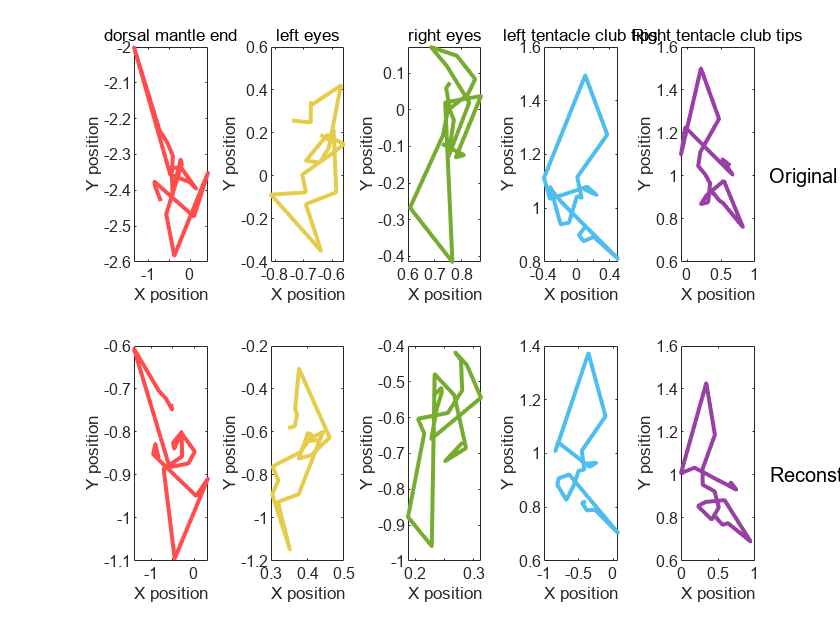

% Draw individual trajectories for each body parts
figure(10);

for i_joint = 1:n_joint
    subplot(2,5,i_joint)
    plot(Xpos(:,i_joint),Ypos(:,i_joint),'LineWidth',2,'Color',colors(i_joint,:));
    xlabel('X position')
    ylabel('Y position')
    title(jointname(i_joint))
end
text(1.2,1,'Original')

for i_joint = 1:n_joint
    subplot(2,5,i_joint+5)
    plot(Xpos_recon(:,i_joint),Ypos_recon(:,i_joint),'LineWidth',2,'Color',colors(i_joint,:));
    xlabel('X position')
    ylabel('Y position')
end
text(1.2,1,'Reconstructed')

fprintf('\nPC 1 ~ %d (explain %.2f)',n_pc,sum(explained(1:n_pc)))


PC 1 ~ 3 (explain 95.88)

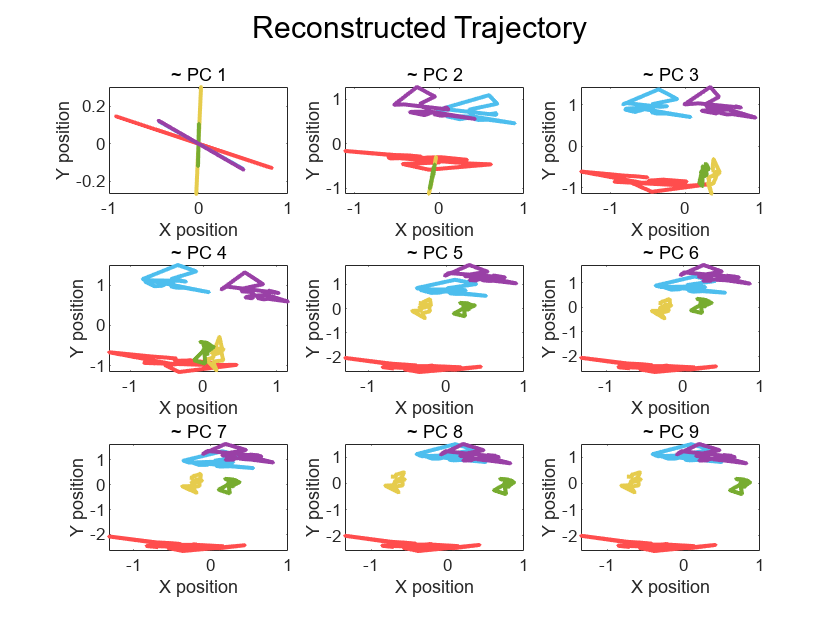


PC 1 ~ 1 (explain 69.72)
PC 1 ~ 2 (explain 92.27)
PC 1 ~ 3 (explain 95.88)
PC 1 ~ 4 (explain 98.22)
PC 1 ~ 5 (explain 99.32)
PC 1 ~ 6 (explain 99.74)
PC 1 ~ 7 (explain 99.93)
PC 1 ~ 8 (explain 100.00)


PC 1 ~ 9 (explain 100.00)

figure
sgtitle('Reconstructed Trajectory')
for n_pc = 1:9 % Choose the pc axis
    % Projecting the time-series data onto the principal components (PC).
    XY_proj  = XY_pos*pc(:,1:n_pc);
    XY_recon = XY_proj*pc(:,1:n_pc)';
    subplot(3,3,n_pc)
    Xpos_recon = XY_recon(:,1:5);
    Ypos_recon = XY_recon(:,6:10);
    recon = plot(Xpos_recon,Ypos_recon,'LineWidth',2);
    for i_joint = 1:n_joint
        recon(i_joint).Color = colors(i_joint,:);
    end
    xlabel('X position')
    ylabel('Y position')
    title(['~ PC ',num2str(n_pc)])
    fprintf('\nPC 1 ~ %d (explain %.2f)',n_pc,sum(explained(1:n_pc)))
    pause(0.5);
end

#### t-SNE

colormaps = jet;
colors_t  = colormaps(1:13:256,:);

#### `!!!Fill the blank!!!`

% Perform t-SNE
rng(8); % For reproducibility
tsne_data = tsne(XY_pos, 'Algorithm', 'exact', 'NumDimensions', 2, 'Perplexity', 2);

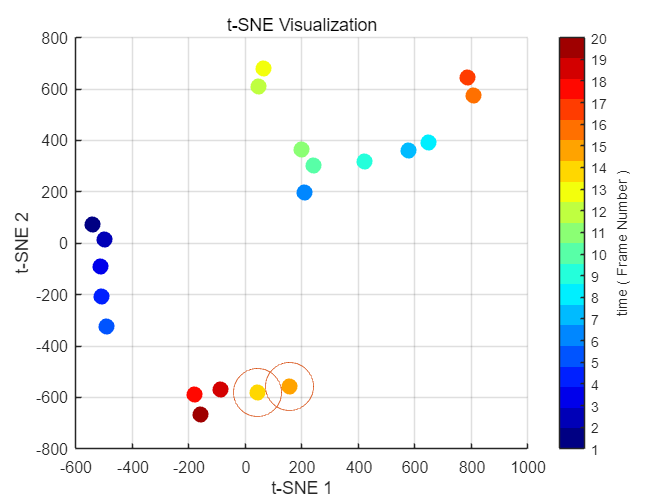

% Plot t-SNE result
figure
scatter(tsne_data(:,1), tsne_data(:,2), 100, colors_t,'filled')
xlabel('t-SNE 1');
ylabel('t-SNE 2');
title('t-SNE Visualization');
grid on;
colormap(colors_t); % Apply custom colormap
cb = colorbar; 
cb.Ticks = linspace(0, 1, 20); 
cb.TickLabels = num2cell(1:20);
cb.Label.String = 'time ( Frame Number )';
hold on
plot(tsne_data(t_strike-1:t_strike,1),tsne_data(t_strike-1:t_strike,2),'o','MarkerSize',30)

#### K-Means Clustering

colors = [1.0000 0.3000 0.3000;
            0.9000 0.8000 0.3000; 
            0.4660 0.6740 0.1880;
            0.3000 0.7450 0.9330;
            0.6000 0.2500 0.6500];

**Elbow Method**

% Choose the number of clusters by using elbow method to determine k
Xtmp  = reshape(Xpos,[],1);
Ytmp  = reshape(Ypos,[],1);
XY    = [Xtmp Ytmp];
label = repmat(1:5,[size(Xpos,1) 1]); label = label(:);

rng(1)
sumd = [];
for k = 1:10
    [~, ~, sumd_k] = kmeans(XY, k);
    sumd(k) = sum(sumd_k);
end

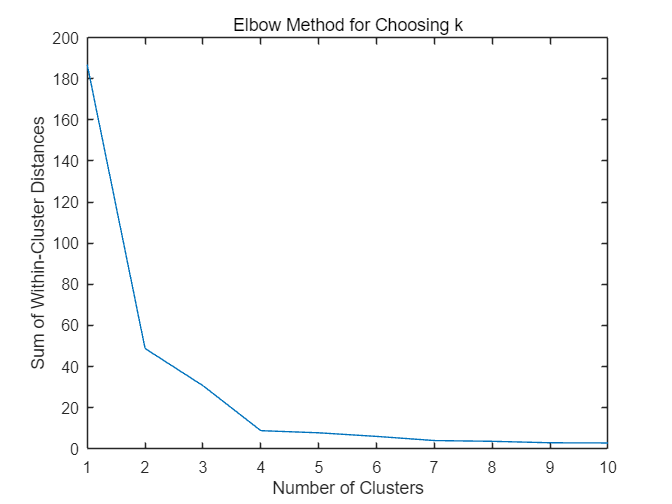

% Plot the elbow curve
figure;
plot(1:10, sumd);
xlabel('Number of Clusters');
ylabel('Sum of Within-Cluster Distances');
title('Elbow Method for Choosing k');

% Perform k-Means Clustering
rng(7); % Fix randomness for reproducibility
k = n_joint; % Choose the number of clusters

#### `!!!Fill the blank!!!`

% Performing k-means clustering
[C_num, C_mean] = kmeans(XY,k);
idx = [1 3 4 5 2];

% Reorder the clustered data
num_reordered = zeros(length(C_num),1);
for i_joint = 1:n_joint
    num_reordered(C_num == idx(i_joint)) = i_joint;
end

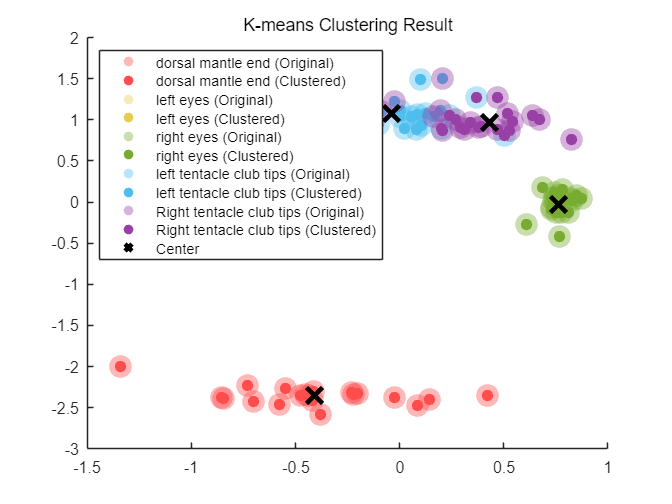

% Plot the clustering result
figure; hold on;

for i = 1:5
    scatter(XY(label==i,1),XY(label==i,2),200,[colors(i,:)],'o','filled','MarkerFaceAlpha',0.4)
    scatter(XY(num_reordered==i,1),XY(num_reordered==i,2),50,[colors(i,:)],'o','filled')
end

scatter(C_mean(idx,1),C_mean(idx,2),200,'x','LineWidth',3,'MarkerEdgeColor',[0 0 0])
title('K-means Clustering Result')
ori_name = cellfun(@(x) [x ' (Original)'],jointname,'UniformOutput',false);
clu_name = cellfun(@(x) [x ' (Clustered)'],jointname,'UniformOutput',false);
lgd      = [ori_name clu_name]';
legend([lgd(:)' {'Center'}],'Location','northwest')

% Count the correct classification
acc = num2str(round(sum(label == num_reordered)/length(label)*100,2));
disp(['The classification accuracy is ' num2str(acc) '%'])

The classification accuracy is 91%
